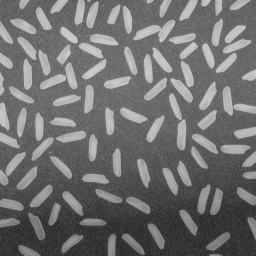

I = imread('rice.png');
imshow(I);

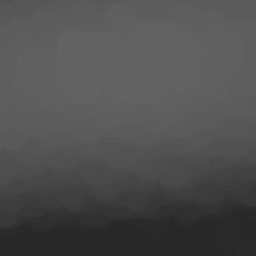

se = strel('disk',15);
background = imopen(I,se);
imshow(background);

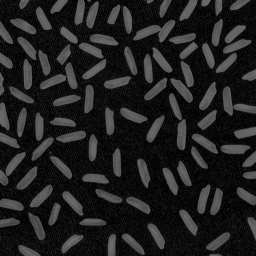

I2 = I - background; % I2 = imtophat(I,strel('disk',15));
imshow(I2);

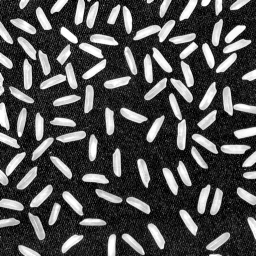

I3 = imadjust(I2);
imshow(I3);

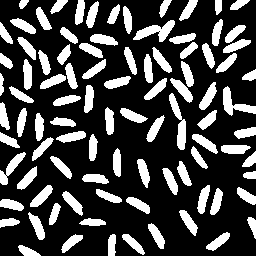

bw = imbinarize(I3);
bw = bwareaopen(bw,50);
imshow(bw);